# Single-event GLM design matrix construction and inference

### Dependencies and setup

This walkthrough uses [CANlab object-oriented analysis functions](http://canlab.github.io) with SPM12 basic functions  (e.g., image reading/writing, HRF) in Matlab.  

Do you have the relevant tools on your Matlab path?  

which create_design_single_event

/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Model_building_tools/create_design_single_event.m


If you get an error, you don't!  You need the [Canlab Core](https://canlab.github.io/repositories/) repository. See [this page](https://canlab.github.io/setup/) for setup instructions.

You also need the Statistics and Machine Learning Toolbox in Matlab. Try this to check:

if isempty(ver('stats')), warning('You do not have the statistics toolbox on your Matlab path. You may/will get errors'); end

### Stats resources

This lab introduces some of the statistics underlying linear models -- the most common way of analyzing data. Linear models are **everywhere** in science, business, education, public policy and health, and beyond. The labs assume that you have some basic background knowledge in statistics from an introductory course, and dive into some important aspects of creating and understanding fMRI models. However, learning statistics is an iterative process! There is so much to understand in statistics, and people can often feel lost because many of concepts are not intuitive at first, and require new ways of thinking. My professors told me "you have to learn it three times before it sinks in". This is true, but even beyond that, you can always go back and deepen your understanding or make new connections. 

This section has some other statistics resources that might help you to go back and refresh or fill in holes so that you can understand this lab sequence better, or deepen your knowledge for the future. One great resource is Jeannette Mumford's crash course in statistics. She is a wonderful teacher and watching her videos will provide an additional explanation of the core concepts needed to understand the GLM. Like statistics in general, learning neuroimaging is an iterative process. In the beginning, it is important to get a broad understanding of the key steps and how neuroimaging can be used to make inferences, but as you progress in your training you will have plenty of opportunities to zoom into specific steps to learn more about particular details and nuances that you may not have fully appreciated the first time around.

- [Basic statistics terminology](https://youtu.be/apt8uAgtgdY) This video gently introduces some of the key concepts that provide the foundation for statistics.

- [Simple Linear Regression](https://www.youtube.com/watch?v=yLgPpmXVVbs) This video explains how a regression works using a single variable.

- [Matrix Algebra Basics](https://www.youtube.com/watch?v=fkZj8QoYjq8) This video provides the background linear algebra needed for understanding the GLM.

- [Multiple Linear Regression](https://www.youtube.com/watch?v=qdOG7YMolmA) This video explains how multiple regression works using linear algebra.

- [Hypothesis Testing](https://www.youtube.com/watch?v=ULeg3DH3g9w) This video covers the basics of hypothesis testing.

- [Contrasts in Linear Models](https://www.youtube.com/watch?v=yLgPpmXVVbs&t=631s) This video provides an overview of how to test hypotheses using contrasts in the context of the GLM.

- [Intepreting Regression Parameters](https://www.youtube.com/watch?v=uClfe4pLrCo) This video covers how to interpret the results from a regression analysis.

- [Mean Centering Regressors](https://www.youtube.com/watch?v=K4S576j90N8) This video covers a more subtle detail of why you might consider mean centering your continuour regression variables.

### Conceptual foundation: A simple experimental design

Let's say that we're examining brain responses to famous faces. We'll construct one of the simplest possible designs, by presenting a face for 3 seconds every 18 sec during fMRI scanning. 

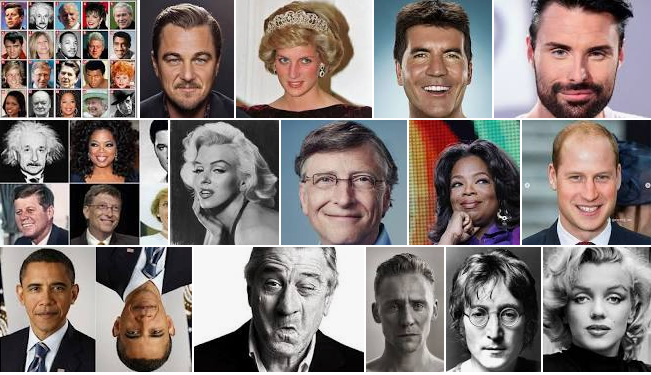

We're going to construct a model (*X*), which is the predicted fMRI signal in a brain area that responds to faces, and fit it to the data. We can use the same model to estimate the amplitude of the response to faces ($\beta_1$) in any voxel or region of a single person's brain (*y*). Fitting the model involves solving the equation $y=X{\hat{\beta}}$, where $y$ is a brain time series (a vector), $X$is the model or "design matrix", and $\hat{\beta}$ is the unknown vector of regression slopes or "parameters". ${\hat}$ or "hat" means something that is estimated from the data during model fitting. 

In our examples here, the regression slopes are equivalent to amplitudes for different psychological conditions. In this first, simplest example, we only have one regressor, corresponding to the "face" condition. There are only two model parameters: one for the "face" regressor of interest ($\beta_1$) and an intercept ($\beta_0$). $X$is a [T x 2] matrix, where T is the number of time points (fMRI images) collected. It has two columns, an intercept (with constant values for every time point) and a "face" regressor whose values are the predicted rise and fall of a hypothetical "face processing" region across time. ${\hat\beta}$ is a [2 *x* 1] vector consisting of $ [{\hat\beta_1}  \; {\hat\beta_0}]^T$.

We can also estimate the amplitude for every voxel in the brain and make a brain map (or $\beta$ map, beta map) out of them. For now, let's consider just a single brain response variable for a single hypothetical brain time series - for example, the average signal in a person's pre-identified "fusiform face area":

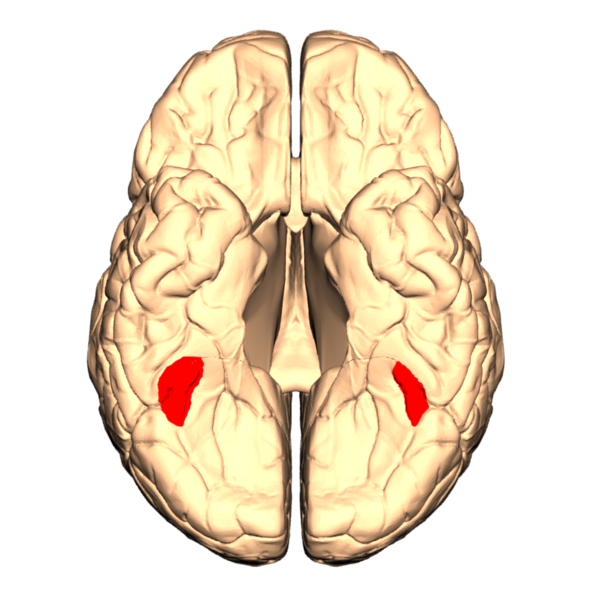

### Create a simple, one-event design

TR = 2;                 % Repetition time for scans; one image every TR; in seconds
ISI = 18;               % Inter-stimulus interval in sec (min time between events)
eventduration = 3;      % Duration of 'neural' events in sec
HPlength = 128;         % High-pass filter length in sec
dononlin = 0;           % Nonlinear saturation model (0 = no, 1 = yes)

create_figure('design');
[X, e] = create_design_single_event(TR, ISI, eventduration, HPlength, dononlin);
drawnow, snapnow


X is the design matrix.  

*e* is the "efficiency", a relative metric of how good the design is compared with others with the same number of time points. Calculating *e* is the reason we need to enter a HP filter length; otherwise, we wouldn't need it to construct the design. We'll come back to *e *later.

To explore the design matrix, try typing X <and then return> to see the values. Remember that the last column is the intercept. The intercept is not shown on the plot.  

To see a heatmap of X, you can also try:

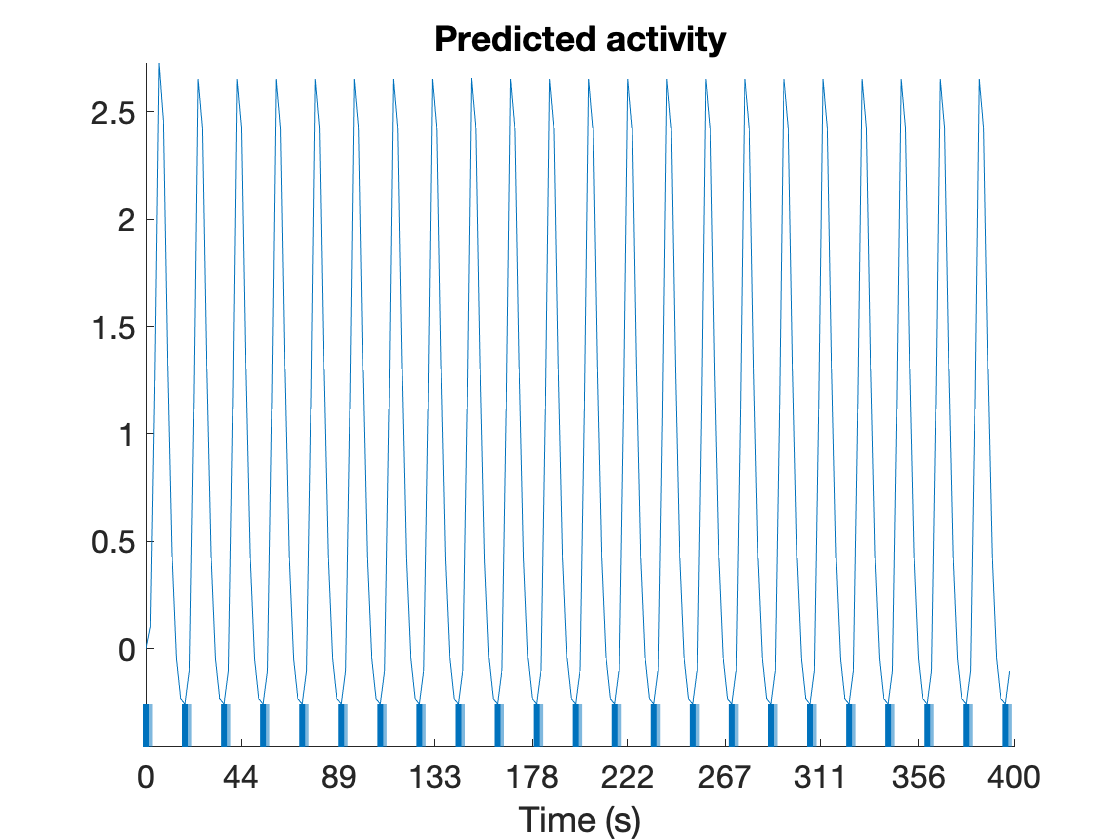

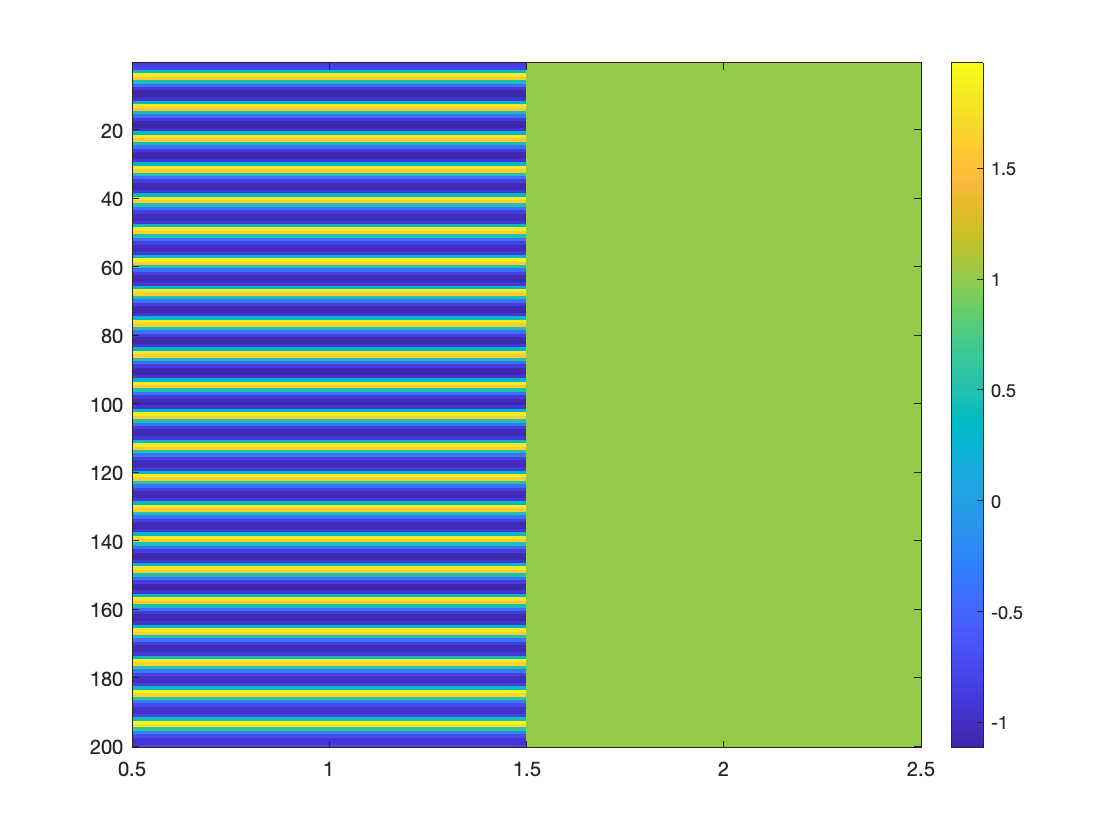


figure; imagesc(X); colorbar
drawnow, snapnow

#### Questions to answer

1. How many columns does X have? How many time points?

2. What does each column represent (i.e., a task event type, etc.)?

3. Make the events really brief (0.5 sec). What happens to the efficiency?

4. Make the events really long (17 sec). What happens to the efficiency?

### `Create simulated data `

`To fit the model, we need some "brain data" (y). This will invariably be noisy, so let's generate some noise:`

noise = randn(size(X, 1), 1);
whos noise

  Name         Size            Bytes  Class     Attributes

  noise      200x1              1600  double              



We've generated a series of normally distributed, or "Gaussian", random values--that's what *randn( )* does--with the same number of time points as X. This isn't very realistic fMRI noise, because real noise drifts slowly over time (is "autocorrelated"). Let's generate some autocorrelated noise instead.  

Then, we'll use the "face" regressor as a simulated true signal, and add the noise to it to simulate empirical data. 

Finally, we'll plot all of these:

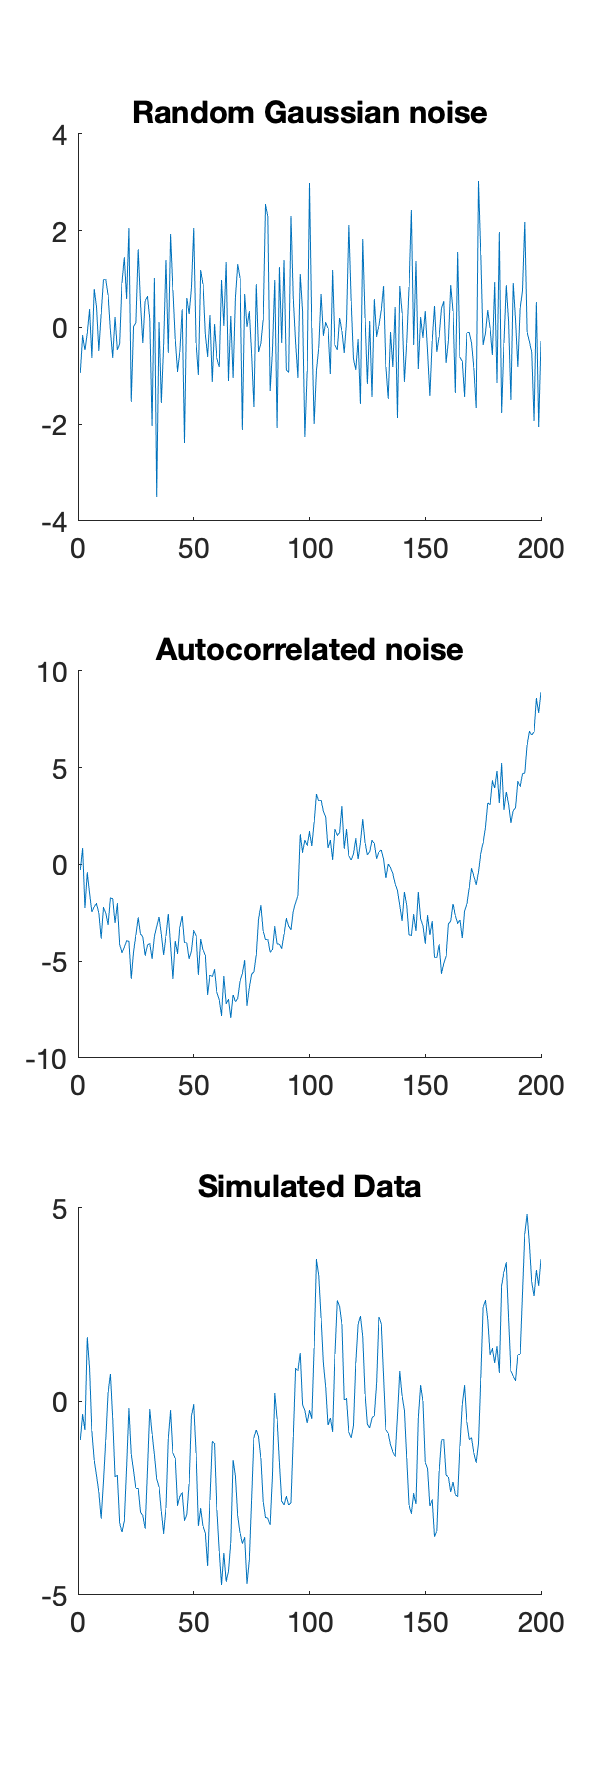

noise_ac = noise_arp(size(X, 1), [.7 .3]);

y = X(:, 1) + .5 * noise_ac;  % simulated data

create_figure('noise and simulated data', 3, 1);
plot(noise)
title('Random Gaussian noise')

subplot(3, 1, 2)
plot(noise_ac)
title('Autocorrelated noise')

subplot(3, 1, 3)
plot(y)
title('Simulated Data')

 The .5 in the expression *.5 * noise_ac *controls the scale of the noise added relative to the signal -- how much noise there is overall.

#### Questions to answer

1. What is the range of the "face" predictor? (it's max minus min). 

*    Note: the code for this wasn't in the example...you may have to look up how!*

2. Change the scaling of the noise.  At what level of noise do you lose the ability to see the pattern of face on/off?  Copy your own code here and make a plot.

### `Fit the model`

The beautiful thing about the GLM in its simplest form is that you can solve $y=X{\hat{\beta}}$ for the unknown $\hat{\beta}$ using one algebraic equation: 

${\hat{\beta}}=(X^TX)^{-1}X^Ty$. This projects the data (*y*) onto the subspace spanned by the columns of *X, *and provides a unique, optimal solution for $\hat{\beta}$, as long as the columns of X are not perfectly colinear. The fitted response $\hat{y}$ is the "reconstructed" data, as close as I can get to the data using a linear combination of model predictors. We can construct the fit $\hat{y}=X\hat\beta$. 

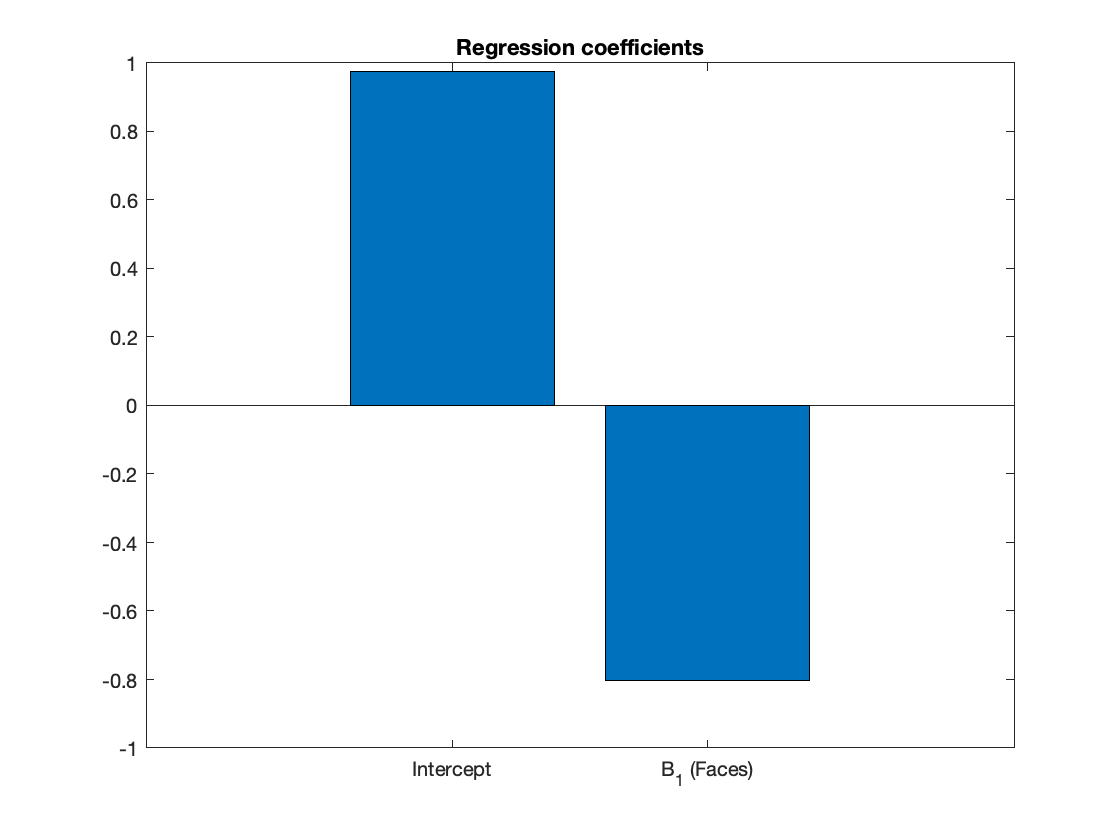

bhat = inv(X' * X) * X' * y;

yhat = X * bhat;

% Now plot the coefficients:

figure; bar(bhat')
set(gca, 'XTickLabel', {'Intercept' 'B_1 (Faces)'});
title('Regression coefficients');

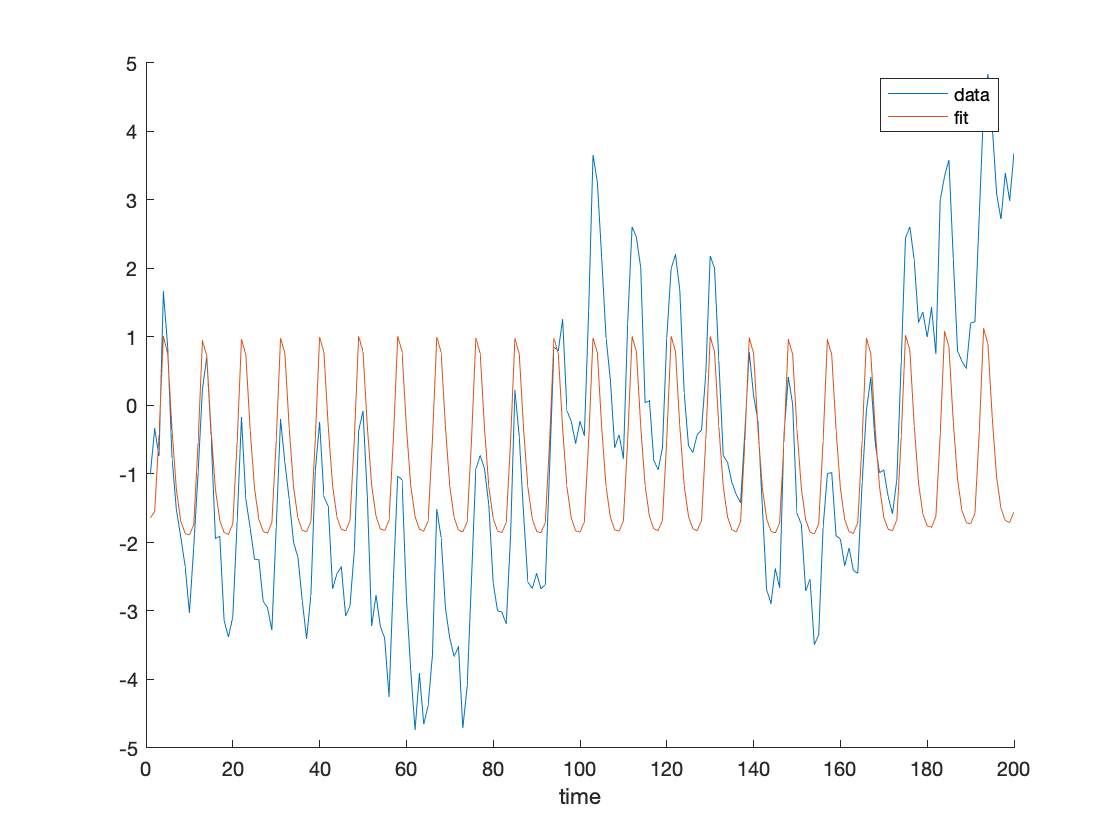


% Now reconstruct the fits and plot it against the "data"

figure; hold on; 
plot(y)
plot(yhat)
legend({'data' 'fit'})
xlabel('time')

#### Questions to answer

1. What is the "beta" (param estimate) for the Faces regressor?  What *should* it be if there were no noise? (You can verify this by changing the simulation...) 

2. Re-run the simulation several times. What do you notice about how the beta for the "faces" regressor changes across repeats? How variable is the parameter estimate?  The **variance** of the parameter estimate across runs is called the **standard error of the estimate, **$var(\hat\beta)$.

3. If you re-ran the simulation many (e.g., 100,000) times, what do you think the average value would be?  The long-run average value is called the **expected value **of the estimate, $E(\hat\beta)$. Will the observed $\hat{\beta}$ ever equal $E(\hat\beta)$ exactly?  Why/why not? 

4. If you increase the noise level, what happens to $var(\hat\beta)$?  What happens to $E(\hat\beta)$?

5. If you decrease the noise level, what happens to $var(\hat\beta)$?  What happens to $E(\hat\beta)$?

### A statistical test for face activation ($\beta_1$)

To perform statistical inference--that is, conduct a hypothesis test--we want to know whether the value we have observed for $\beta_1$is unlikely to be due to chance.  To perform the test, we propose a **null hypothesis. **This is that there is no true activation, $\beta_1=0$, and the observed deviation from 0 is due to chance. We then evaluate how (un)likely it would be to observe the value $\hat\beta$ under the null hypothesis. This value is the P-value, where P stands for probability.  If P is low (e.g., P < 0.05 by convention, or often P < 0.001 in neuroimaging studies) we might reject the null hypothesis in favor of the alternative hypothesis, here that $\beta_1\not=0$. We'll learn more about **thresholding**, or more principled methods of choosing P-values, later. 

How do we evaluate this likelihood?  The standard way is to make a few assumptions and use **parametric statistics, **which gives us theoretically informed values based on a **test statistic**, which is generally a ratio between an estimate of signal strength and error, or *signal / noise, *with a known probability distribution. This gives us an easy-to-calculate and usually robust estimate of the likelihood of observing $\hat\beta$ (and, more generally, the data I observe) under the null hypothesis. 

The most widely used test statistic is the **t statistic, **which is a estimate divided by its standard error, or $\hat\beta/se(\hat\beta)$. We already know how to estimate $\hat\beta$ using regression. Now we have to estimate its standard error.  

#### Statistical inference: A simulation-based example

If we could repeat the test many times (e.g., 10,000 or more)  given the same ground truth ($\beta_1=0$) and noise level, we could estimate $se(\hat\beta)$directly.  It would be $se(\hat\beta)=\sqrt{var(\hat\beta_j)}$ across *j* repetitions.  $var(\hat\beta)$is the **variance**, a measure of spread, and is calculated as $var(\hat\beta)=\sum{(\hat\beta_j-\bar{\hat\beta})^2}/(J-1)$, where* j *indexes each of *J* repetitions and the "bar" denotes the mean across *J* repetitions. Let's try it here:

% Set the noise level (formally, noise standard deviation) here:
% -------------------------------------------------------
Noise_std =10

Noise_std = 10

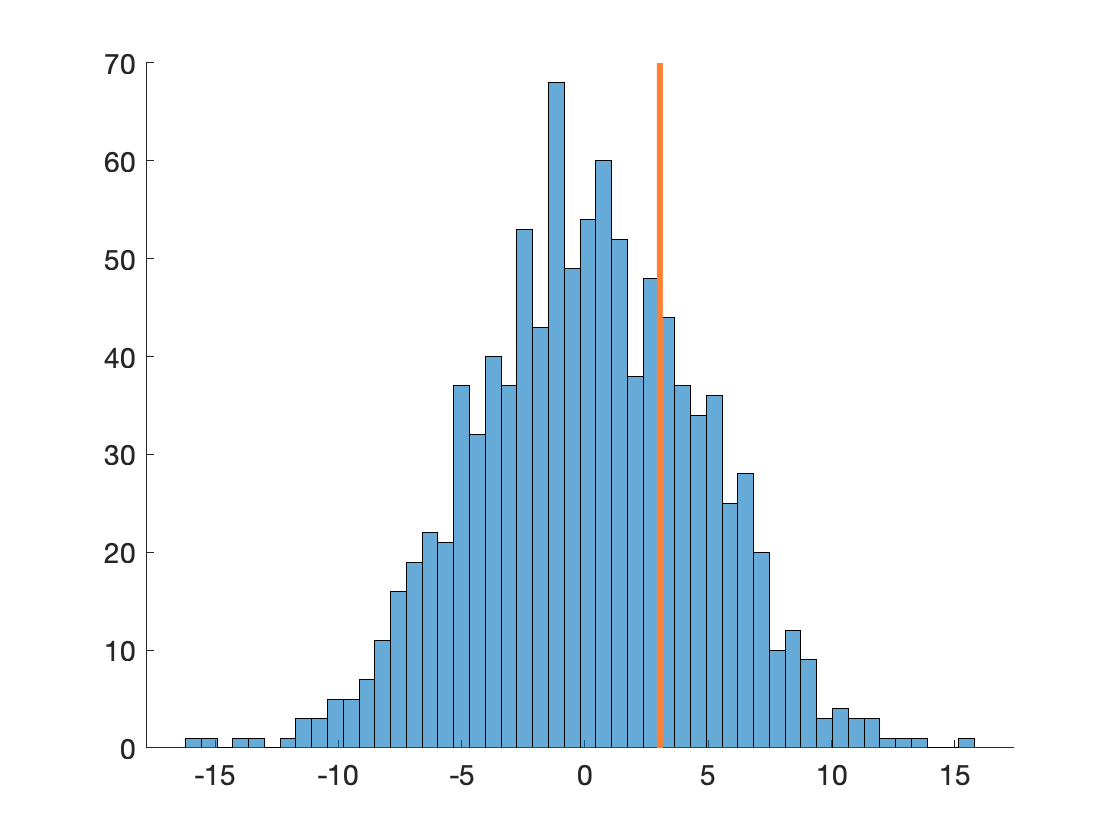


% Observed effect in sample
% -------------------------------------------------------
noise_ac = noise_arp(size(X, 1), [.7 .3]);

y = X(:, 1) + Noise_std * noise_ac;  % simulated data
bhat_obs = inv(X' * X) * X' * y;  % parameter estimates
bhat_obs = bhat_obs(1);

% Null hypothesis simulation - Monte Carlo
% -------------------------------------------------------

bhat_null = zeros(1000, 1);   % initialize a vector to store 1,000 repeats, each on a new sample

for j = 1:1000
    
    noise_ac_j = noise_arp(size(X, 1), [.7 .3]); % new noise sample
    
    y = 0 * X(:, 1) + Noise_std * noise_ac_j;  % simulated data - no true effect
    bhat = inv(X' * X) * X' * y;  % parameter estimates
    
    bhat_null(j, 1) = bhat(1);
    
end

create_figure('null hypothesis sim'); 
histogram(bhat_null, 50)

h = plot_vertical_line(bhat_obs);
set(h, 'LineWidth', 3, 'Color', [1 .5 .2])

Here we've simulated the null hypothesis case by assuming we know the true noise level, which is built into our simulation. The **P-value** here would be based on the probability of observing bhat_obs or larger in these simulations. Let's calculate it below. We calculate each "tail" separately, taking the lowest value in either direction but mulitplying by two to correct for the fact that bhat_obs could theoretically lie in either tail. This is a **two-tailed** P-value, and is standard.

P_lower = sum(bhat_null < bhat_obs) ./ length(bhat_null);
P_upper = sum(bhat_null > bhat_obs) ./ length(bhat_null);
P = 2 * min(P_lower, P_upper)

P = 0.5380


if P < 0.05, disp('Significant!'), else, disp('Not significant :('), end

Not significant :(


*An important note*: This is not a valid method to use in practice, because we don't know the true level of noise (i.e., the true error variance, as we'll see below). So we'll have to use other methods in practice.

#### Questions to answer

1. Increase the noise level.  What happens to the null distribution for beta?

2. Re-run the simulation with lower noise and with higher noise.  What happens to the likelihood of finding a significant P-value?

#### Statistical inference: A parametric t-test

The trouble is that with a real dataset, we don't know the true noise level and can't repeat the experiment many times, so we have to use our sample to estimate the noise level from the data too. 

It turns out that we can estimate $var(\hat\beta)$ from a single sample, if we know two quantities: The **sample error variance**, which is related to how much error variability there is among your individual obervations, and the **error degrees of freedom, **which is how many independent observations there are in your sample. We can estimate the sample variance from the **residuals **(*e*), the errors that I cannot explain with my model: $\hat{e}=y-\hat{y}=y-X\hat\beta$. Because of the **central limit theorem**, $var(\hat\beta)$is the variance of *e* divided by the square root of the degrees of freedom, or $var(\hat\beta)=var({\hat{e})/\sqrt{df}$.

Now for the degrees of freedom. If all observations are independent random draws from a population, this is generally the number of samples minus the number of parameters we have estimated. Here, $df = 200 - 2 = 198$. Note that in an fMRI time series, the observations are not independent, because they are **autocorrelated** -- and we have fewer degrees of freedom than we think. Estimating them requires specialized time series statistics that we'll discuss later, so for now we'll just use the naive estimate of *df*.  Thus:  


$$t=\hat\beta/\sqrt{var(\hat\beta)}$$



$$var(\hat\beta)=var({\hat{e})/df=var({\hat{e})/198$$


The *t* statistic has a known probability distribution under the null hypothesis, based on the df (which in turn in based on the sample size and model complexity). Thus, it's possible to convert any given *t* value and df to a P-value, which will be valid as long as all the assumptions (e.g., of independent observations) hold. The P-value is the area under the (null hypothesis) *t* distribution more extreme than the observed *t* value. 

% Set the noise level (formally, noise standard deviation) here:
% -------------------------------------------------------
Noise_std =10

Noise_std = 10


% Observed effect in sample
% -------------------------------------------------------
noise_ac = noise_arp(size(X, 1), [.7 .3]);

y = X(:, 1) + Noise_std * noise_ac;  % simulated data
bhat_obs = inv(X' * X) * X' * y;  % parameter estimates
e = y - X * bhat_obs;

% Parametric t-test
% -------------------------------------------------------

df = length(y) - size(X, 2);      % Assumed degrees of freedom. Correct if no autocorrelation 

t = bhat_obs ./ sqrt(var(e) ./ df);

P = 2 .* min(tcdf(t, df), 1-tcdf(t, df));
P = P(1);                % we are interested in "face" regressor (param 1), not the intercept
disp(P)

    0.8149




if P < 0.05, disp('Significant!'), else, disp('Not significant :('), end

Not significant :(


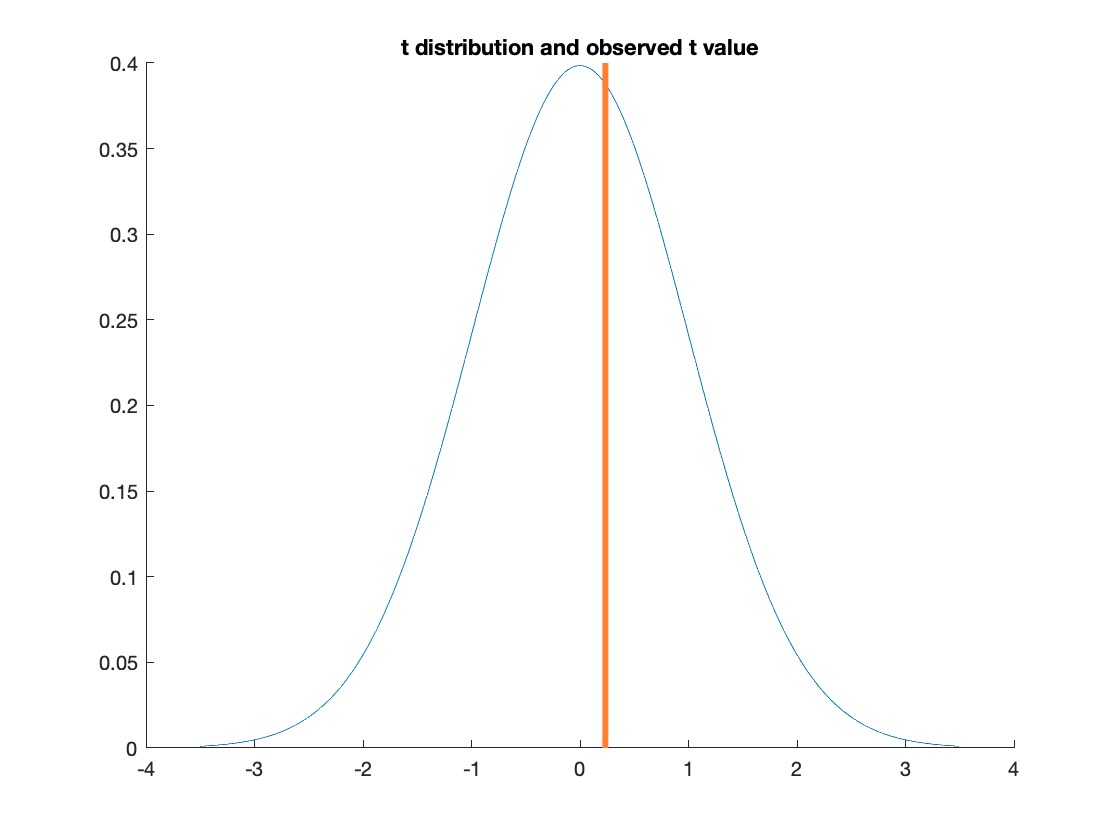


% Visualize the t-distribution and observed t-value
% -------------------------------------------------------
tprob = tpdf([-3.5:.01:3.5], df);

figure; hold on;

plot([-3.5:.01:3.5], tprob);

h = plot_vertical_line(t(1));
set(h, 'LineWidth', 3, 'Color', [1 .5 .2])
title('t distribution and observed t value')

As you can see in the image below, the t distribution looks like a standard Normal distribution (the Gaussian distribution or "bell curve"), but it has tails that are a bit fatter. The lower the df, the fatter the tails are. This means that the t distribution adjusts for the fact that we're estimating the error variance based on a limited sample.  

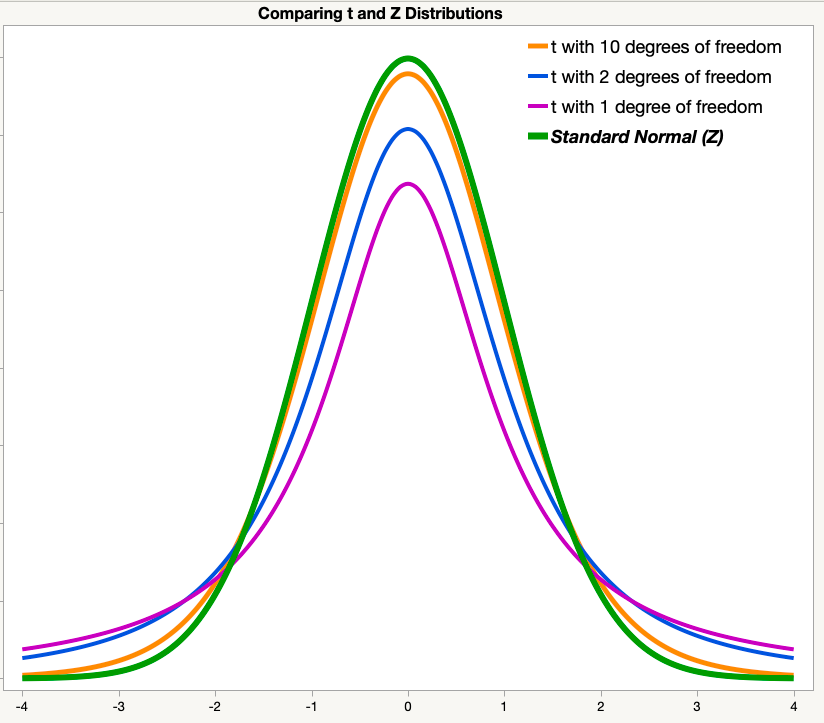

Fun fact: the t distribution was derived by hand, by William Gossett, when analyzing beer samples at the Guinness brewery. He modestly called himself "Student", so the distribution is called the "Student's t distribution."

#### Questions to answer

1. Increase the noise level.  What happens to the null t distribution?  Why?

2. Decrease the noise level. At what value do you start to get frequently significant results?

2. What does decreasing or increasing the noise level affect? (hint: What happens to the t statistic?) Why?

#### Statistics in Matlab

Finally, in practice, we don't need to work through the calculations for t-statistics and other tests manually.  Matlab has many statistical tests built in, including **ttest**, **ttest2**, **regress**, **glmfit**, **fitlme**, and many more. Generally, these are in the Statistics and Machine Learning Toolbox. 

Here's an example, using glmfit to run our regression. We'll leave off the intercept and pass in only the "face" regressor, as glmfit adds an intercept (as the first regressor) by default. the "stats" variable is a *structure-*class variable containing t-values, p-values, and more. For more info and usage, type "help glmfit".  

% Observed effect in sample
% -------------------------------------------------------
noise_ac = noise_arp(size(X, 1), [.7 .3]);

y = X(:, 1) + Noise_std * noise_ac;  % simulated data
bhat_obs = inv(X' * X) * X' * y;  % parameter estimates
e = y - X * bhat_obs;

% Parametric t-test on face regressor via glmfit
% -------------------------------------------------------

[b dev stats] = glmfit(X(:, 1), y);
stats.t(2)

ans = 0.0582

stats.p(2)

ans = 0.9537


% Let's print output for the "face" regressor:
fprintf('t(%3.0f) = %3.2f, p = %3.6f\n', stats.dfe, stats.t(2), stats.p(2))

t(198) = 0.06, p = 0.953650


### Alternatives to parametric tests

There are several alternatives to parametric tests. If we know the true error distribution, a Monte Carlo simulation may be appropriate. However, we rarely if ever do, in practice.  The two most common alternatives are **bootstrap** tests and **permutation** tests. Both are **resampling methods**, which use the data to estimate the likelihood of the data under the null hypothesis. They require fewer assumptions, and are often preferred to parametric tests - but they are much more computationally expensive and more complex procedures, so there are more ways to get things wrong procedurally when conducting a test.

Bootstrap tests take repeated samples of the data to estimate the standard errors of parameter estimates.  [Nonparametric tests](https://onlinelibrary.wiley.com/doi/full/10.1002/hbm.1058) simulate the null hypothesis by shuffling or flipping the labels on conditions, groups, or data (e.g., fMRI images). They require even weaker assumptions, chiefly: (1) symmetry around a test statistic (e.g., 0) under the null hypothesis, and (2) exchangeability under the null hypothesis. Exchangeability relates to independence, and concerns whether the labels can be shuffled randomly without changing the distribution of the summary test statistic of interest. If, for example, you're studying twins, you can't randomly flip labels for one twin and not the other, because you'd be breaking a natural relationship in the data. 

Finally, other tests based on, e.g., ranking scores (e.g., "Spearman's rank correlation") or testing the signs of effects (e.g., "sign test"), are also sometimes called "nonparametric tests". These are distinct from the bootstrap and permutation tests we are discussing here, because they are parametric tests on transformations of the data designed to make violations of the assumptions less problematic.  